# Phase function interpolator

## Description

This script loads in a densly sampled (5nm wavelength steps, 2% volume-volume concentration steps & 5000 angular points )data set for the phase function and interpolates to any requested wavelength [400,1700] nm, volume fraction [0,0.227] and angle [0,pi] triplet.

close all
clear all
clc

load("res_IL_400_1700_all_props_publish.mat")

%generating 3D dataset
lambda_vec  = [res.lambda]';
phip_vec    = res(1).phi_p';
ang_vec     = res(1).angrad';

%init full data set
full_PF_data = zeros(length(lambda_vec),length(phip_vec),length(ang_vec));
for i = 1:size(res,2)
    %extracting phase function (all concentration) for given wavelgnth
    full_PF_data(i,:,:) = res(i).PF_dep';
end


## Interpolating

%target wavelengths [m]
target_lambda = [600]*1e-9;

%target volume fractions [-]
target_phi_p = [0.1];

%target angles [rad]
target_theta = linspace(0,pi,300);

%putting everything into column vectors
target_lambda   = target_lambda(:);
target_phi_p    = target_phi_p(:);
target_theta    = target_theta(:);

% Create linear interpolant
F = griddedInterpolant({lambda_vec, phip_vec, ang_vec}, full_PF_data, 'linear', 'none');

%generating query vector
[Xq, Yq, Zq] = ndgrid(target_lambda, target_phi_p, target_theta);
%interpolation
Vq = squeeze(F(Xq, Yq, Zq));

%checking normalization
2*pi*trapz(target_theta,Vq.*sin(target_theta))

ans =       0.99995


%re-normalizing
Vq = Vq/(2*pi*trapz(target_theta,Vq.*sin(target_theta)));




## example figure

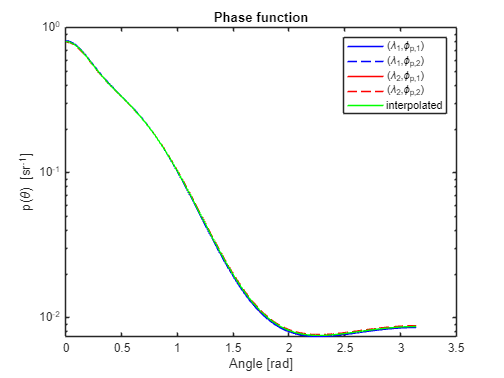

%identifying closest wavelengths & volume fraction
i_phip1     = find(target_phi_p>phip_vec,1,'last');
i_lam1      = find(target_lambda>lambda_vec,1,'last');

figure
%plotting closest phase functions
semilogy(ang_vec,res(i_lam1).PF_dep(:,i_phip1),'b')
hold on
semilogy(ang_vec,res(i_lam1).PF_dep(:,i_phip1+1),'b--')
semilogy(ang_vec,res(i_lam1+1).PF_dep(:,i_phip1),'r')
semilogy(ang_vec,res(i_lam1+1).PF_dep(:,i_phip1+1),'r--')
%interpolated vector
semilogy(target_theta,Vq,'g')
xlabel('Angle [rad]')
ylabel('p(\theta) [sr^{-1}]')
title('Phase function')
legend('(\lambda_1,\phi_{p,1})','(\lambda_1,\phi_{p,2})',...
    '(\lambda_2,\phi_{p,1})','(\lambda_2,\phi_{p,2})','interpolated')